# SIM.6. State Estimation of the Coupled Tanks System

h1 = 0 % cm

h1 = 0

h2 = 0 % cm

h2 = 0

g = 981 % cm/s^2

g = 981

d = 4.45 % cm

d = 4.4500

A_1 = (pi*d^2)/4 % cm^2

A_1 = 15.5528

A_2 = A_1 % cm^2

A_2 = 15.5528

d_or = 0.48 % cm

d_or = 0.4800

A_b = (pi*d_or^2)/4 % cm^2

A_b = 0.1810

A_e = A_b % cm^2

A_e = 0.1810

c_1 = A_b*sqrt(2*g)

c_1 = 8.0153

c_2 = A_e*sqrt(2*g)

c_2 = 8.0153

h_10 = 15

h_10 = 15

h_20 = 15

h_20 = 15

A = [-c_1/(2*A_1*sqrt(h_10)) 0; c_1/(2*A_2*sqrt(h_10)) -c_2/(2*A_2*sqrt(h_20))]

A =    -0.0665         0
    0.0665   -0.0665


B = [1/A_1; 0]

B =     0.0643
         0


C = [0 1];
q_i0 = c_1*sqrt(h_10)  % cm^3/s

q_i0 = 31.0433

obs = ctrb(transpose(A), transpose(C))

obs =          0    0.0665
    1.0000   -0.0665


rank(obs)

ans = 2

C = [1 0];
obs = ctrb(transpose(A), transpose(C))

obs =     1.0000   -0.0665
         0         0


rank(obs)

ans = 1

w_n = 0.2 % rad/s

w_n = 0.2000

DesPoles = roots([1 1.4*w_n w_n^2])

DesPoles =   -0.1400 + 0.1428i
  -0.1400 - 0.1428i


C = [0 1];
G = acker(A',C',DesPoles)'

G =     0.3877
    0.1469


eig(A-G*C)

ans =   -0.1400 + 0.1428i
  -0.1400 - 0.1428i


ICs = 0

ICs = 0

q_i = q_i0

q_i = 31.0433

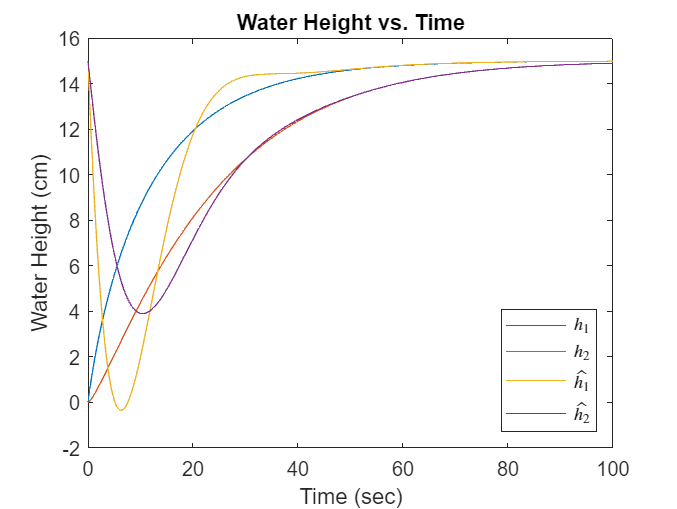

out = sim('CTS_State_Estimator', 100);

plot(out.h1.Time, out.h1.Data)
hold on
plot(out.h2.Time, out.h2.Data)
plot(out.h_hat.Time, out.h_hat.Data)
hold off
title("Water Height vs. Time")
xlabel("Time (sec)")
ylabel("Water Height (cm)")
legend("$h_1$", "$h_2$", "$\hat{h_1}$", "$\hat{h_2}$", "location", "southeast", "interpreter", "latex")

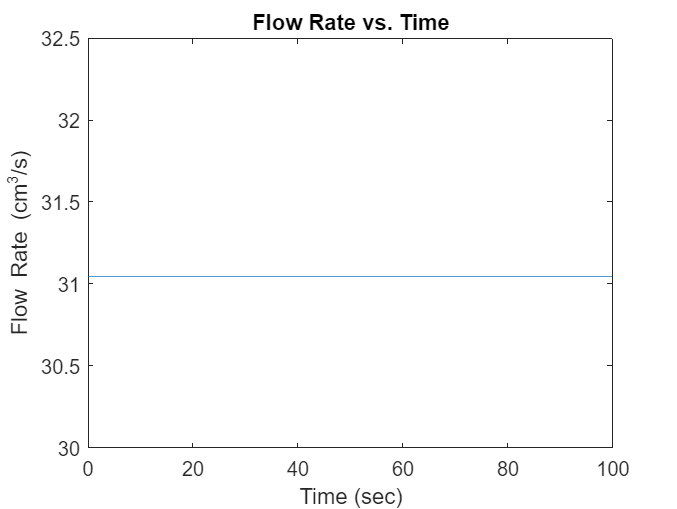


plot(out.tout, out.q_i.Data)
yline(q_i, "Color", [0 0.4470 0.7410])
title("Flow Rate vs. Time")
xlabel("Time (sec)")
ylabel("Flow Rate (cm^3/s)")

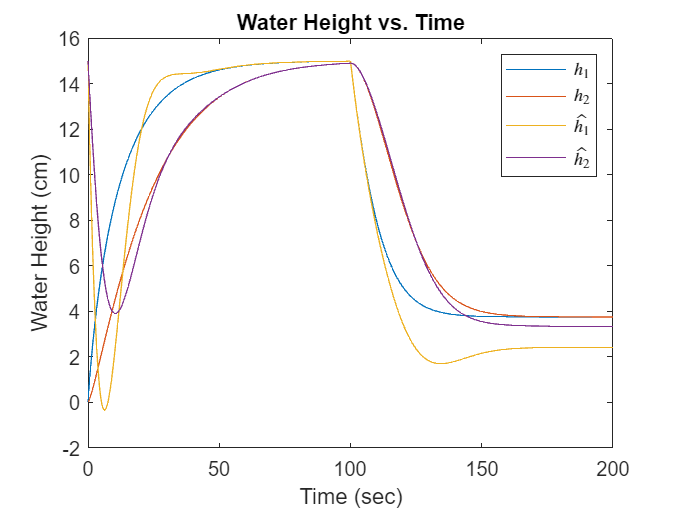

out = sim('CTS_State_Estimator_Fault', 200);

plot(out.h1.Time, out.h1.Data)
hold on
plot(out.h2.Time, out.h2.Data)
plot(out.h_hat.Time, out.h_hat.Data)
hold off
title("Water Height vs. Time")
xlabel("Time (sec)")
ylabel("Water Height (cm)")
legend("$h_1$", "$h_2$", "$\hat{h_1}$", "$\hat{h_2}$", "location", "northeast", "interpreter", "latex")

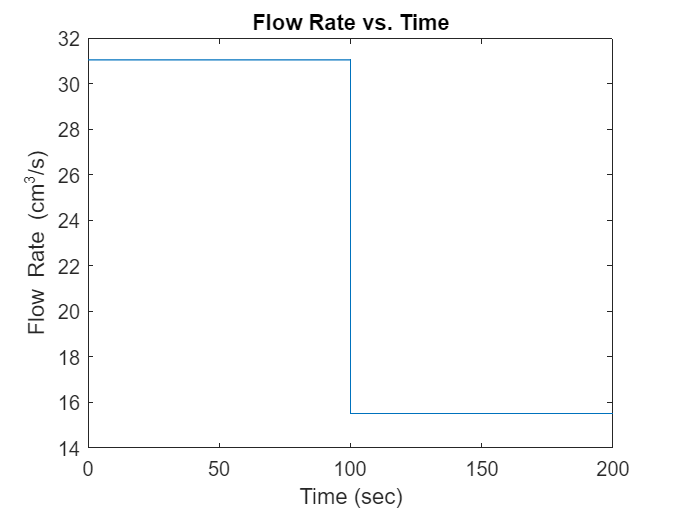


plot(out.q_i.Time, out.q_i.Data)
title("Flow Rate vs. Time")
xlabel("Time (sec)")
ylabel("Flow Rate (cm^3/s)")